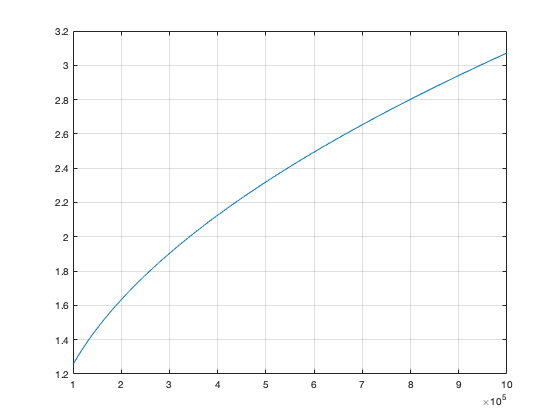

l1 = 0.055*0.444;
m = 140;
g = 9.8;
k = 1.0*10^5:10^4:10.0*10^5;
%l2 = l1 + (m*g./k).*sqrt(2.*k*l1/(m*g)-1);
%K = k/2.0 .*l2.^2 + k*l1.*l2;
K = 3.*k*l1^2/2.0 + 2*m*g*l1*sqrt(2*k*l1/(m*g)-1)...
    +m*g*l1 - m^2*g^2./(2*k);
velocity = sqrt(K/m);
plot(k,velocity)
grid on

%f = fit(k',performance','power1')